# Example 6.1: PCA Analysis for Gibbs Reactor Data

Note: this script reproduces Example 6.1 (Section 6.1) of **Statistics for Chemical Engineers**: principal component analysis of the Gibbs reactor data. Victor Z UW-Madison, 2019 PCA analysis of gibbs reactor [https://www.mathworks.com/help/stats/pca.html](https://www.mathworks.com/help/stats/pca.html)

clc; clear all; close all hidden;

## Data

create data set

load ('./Data/gibbs_hightemp_class.dat')
datahigh=gibbs_hightemp_class;
load ('./Data/gibbs_lowtemp_class.dat')
datalow=gibbs_lowtemp_class;
data=[datahigh;datalow];
datan=data;
n=length(datan);

% corrupt data with noise to hide pattern 
rng(1); % For reproducibility 
x1 = datan(:,2)+randn(n,1)*0.1; % pressure 
x2 = datan(:,3)+randn(n,1)*0.1; % conversion
 y = datan(:,1)+randn(n,1)*0.1; % temperature
X=[y x1 x2];

## Data in 3D and 2D

visualize the data in 3D (the clusters reveal)

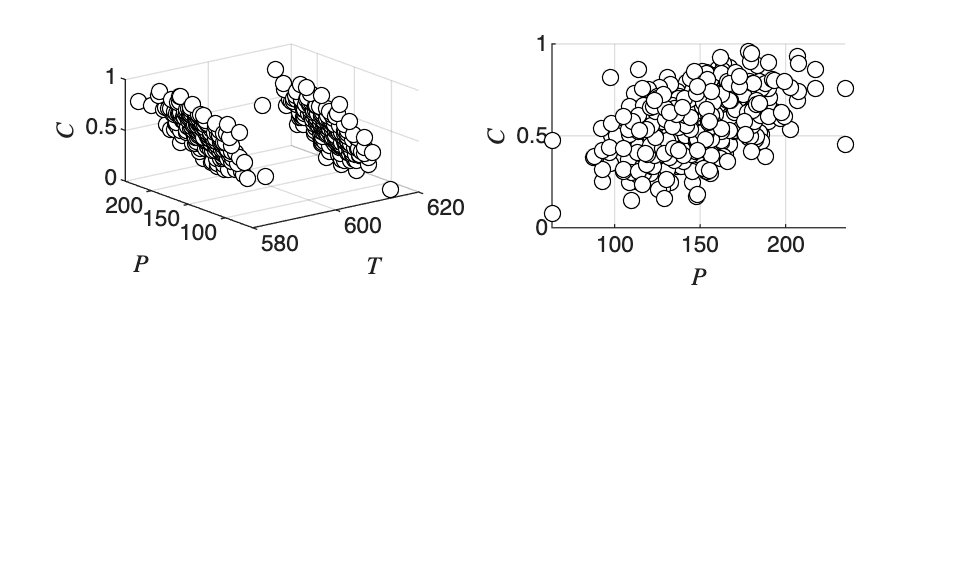

figure(1)
subplot(2,2,1)
scatter3(X(:,1),X(:,2),X(:,3),'blacko','MarkerFaceColor','w')
grid on
zlabel('$C$','Interpreter','latex')
ylabel('$P$','Interpreter','latex')
xlabel('$T$','Interpreter','latex')

% visualize the data in 2d (the clusters are hidden)
figure(1)
subplot(2,2,2)
scatter(x1,x2,'blacko','MarkerFaceColor','w')
grid on
xlabel('$P$','Interpreter','latex')
ylabel('$C$','Interpreter','latex')

## Projection with PCA

lets visualize the entire data in 2D using PCA

[coeff,score,latent,~,explained,mu] = pca(X,'Algorithm','eig')

coeff =     0.0001    1.0000    0.0069
    1.0000   -0.0001   -0.0028
    0.0028   -0.0069    1.0000


score =    19.0583   14.8646   -0.0229
   22.9741   14.9103    0.0379
   -6.7556   14.9410    0.0010
   -1.3368   14.9738    0.0090
   16.7262   15.0805   -0.0988
    9.5218   14.8647    0.0458
    3.7134   14.9885    0.0243
   -0.5618   14.7760    0.1179
  -10.7290   15.0833    0.1663
   41.5627   15.0551    0.0408
  -15.1630   14.8805   -0.1857
  -16.8449   14.9960   -0.0851
   11.9315   14.9240   -0.0480
   22.5239   15.2554   -0.0114
   -6.5377   15.2771   -0.0261


latent =   640.1332
  225.5341
    0.0097


explained =    73.9460
   26.0529
    0.0011


mu =   598.1538  147.8563    0.5754


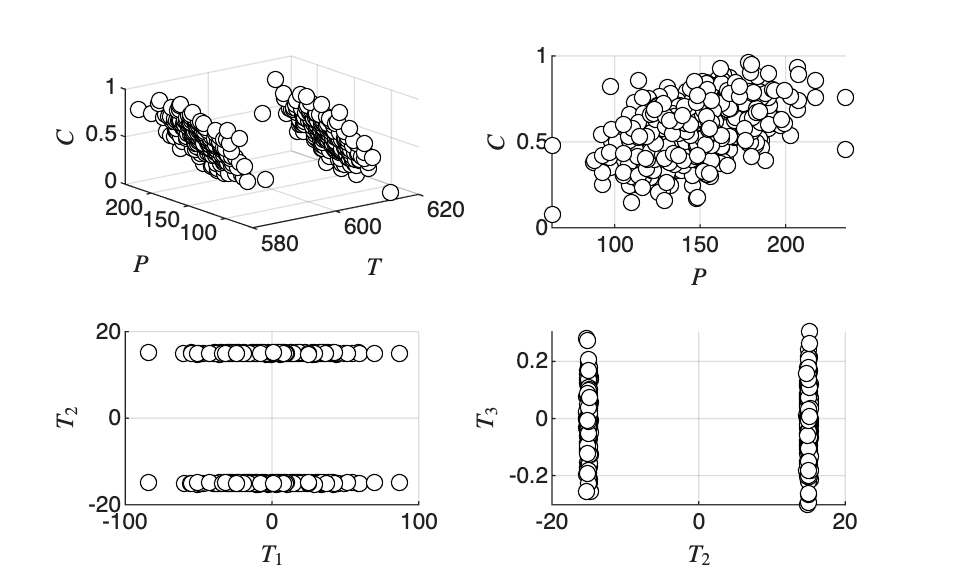


figure(1)
subplot(2,2,3)
scatter(score(:,1),score(:,2),'blacko','MarkerFaceColor','w')
grid on
xlabel('$T_1$','Interpreter','latex')
ylabel('$T_2$','Interpreter','latex')

figure(1)
subplot(2,2,4)
scatter(score(:,2),score(:,3),'blacko','MarkerFaceColor','w')
grid on
xlabel('$T_2$','Interpreter','latex')
ylabel('$T_3$','Interpreter','latex')

print -depsc -r1200 ch6_pca_gibbs.eps

## PCA from the eigenvectors of the covariance

now let's try to get the eigenvectors without using PCA built-in function normalize original matrix and check that each column has zero mean

mun=mean(X);
Xn=X-mun;
mean(Xn)

ans = 1.0e-12 *

   -0.1025    0.0077   -0.0001



% form covariance matrix
Sigma=Xn'*Xn

Sigma = 1.0e+05 *

    1.1254    0.0003   -0.0078
    0.0003    3.1942    0.0090
   -0.0078    0.0090    0.0001



% get eigenvectors and eigenvalues from covariance matrix
[W,lam]=eigs(Sigma)

W =    -0.0001   -1.0000    0.0069
   -1.0000    0.0001   -0.0028
   -0.0028    0.0069    1.0000


lam = 1.0e+05 *

    3.1943         0         0
         0    1.1254         0
         0         0    0.0000


lam=diag(lam);

% get principal components and visualize
T=Xn*W

T =   -19.0583  -14.8646   -0.0229
  -22.9741  -14.9103    0.0379
    6.7556  -14.9410    0.0010
    1.3368  -14.9738    0.0090
  -16.7262  -15.0805   -0.0988
   -9.5218  -14.8647    0.0458
   -3.7134  -14.9885    0.0243
    0.5618  -14.7760    0.1179
   10.7290  -15.0833    0.1663
  -41.5627  -15.0551    0.0408
   15.1630  -14.8805   -0.1857
   16.8449  -14.9960   -0.0851
  -11.9315  -14.9240   -0.0480
  -22.5239  -15.2554   -0.0114
    6.5377  -15.2771   -0.0261



% now show that the principal components can be used to approximate Sigma
Sigma1 = lam(1)*W(:,1)*W(:,1)'

Sigma1 = 1.0e+05 *

    0.0000    0.0004    0.0000
    0.0004    3.1942    0.0090
    0.0000    0.0090    0.0000


Sigma12 = lam(1)*W(:,1)*W(:,1)'+lam(2)*W(:,2)*W(:,2)'

Sigma12 = 1.0e+05 *

    1.1254    0.0003   -0.0078
    0.0003    3.1942    0.0090
   -0.0078    0.0090    0.0001


Sigma123 = lam(1)*W(:,1)*W(:,1)'+lam(2)*W(:,2)*W(:,2)'+lam(3)*W(:,3)*W(:,3)'

Sigma123 = 1.0e+05 *

    1.1254    0.0003   -0.0078
    0.0003    3.1942    0.0090
   -0.0078    0.0090    0.0001


## Note

As in the book, a small eigenvalue reveals a redundant dimension, caused by the high correlation between pressure and conversion: we can drop one of them and keep most of the information.